# NB-IoT sim script

## nbiot parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=1;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz
Fs=numSC*SCS;
cpLen=4;
L = 1;  % Upsampling factor



## sim parameters

%data
%numSym=round(10000/(numSC*2);
numSym=2;

randomData=true;
enableFilters=true;
%channel
perfectChannel=true;%no  awgn
maxDopplerShift=1e3;
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=10; %signal to noise ratio in dB
%loops
nLoops=1;
loopSNR=false;
SNRstepsize=2;
loopDoppler=false;
dopplerStepsize=0.1e3;

plotScatterPlot=true;
plotSpec=true;

## tx

%generate data
dataLength=numSym*numSC*2;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=3;%generate symbols with certain value {0-3}
    messageBits=transpose(repmat(dec2bin(symbol,2)-'0',1,numSym*numSC));% -'0' to convert binary string to vector
end
%turn binary vector into vector of qpsk symbols
qpskSymbols=generateQpskSymbols(messageBits)

messageInts =      0
     0
     0
     0
     3
     0
     2
     3
     3
     3


qpskSymbols =    0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i


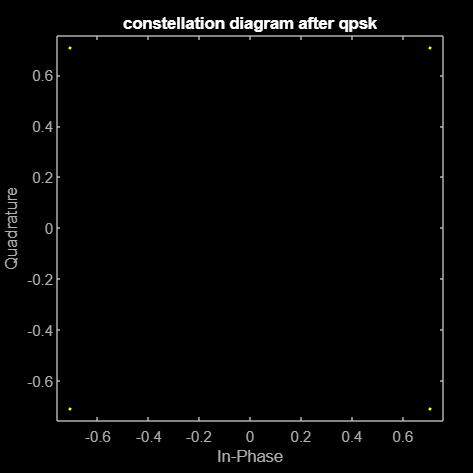


if plotScatterPlot
    %plot scatterplot
    figure;
    scatterplot(qpskSymbols);
    title('constellation diagram after qpsk');
end

% generate ofdm symbols,  numSC samples per symbol in time domain + CP
ofdmTimeSignal=generateOfdmSignal(qpskSymbols,numSC,SCS,cpLen)

ofdmTimeSignal =    0.1768 + 0.1021i
   0.0000 - 0.2357i
   0.1768 - 0.1021i
   0.2946 - 0.1021i
   0.0000 + 0.0000i
  -0.1768 + 0.5735i
   0.1768 + 0.1021i
  -0.2357 + 0.0000i
   0.1768 - 0.1021i
  -0.1768 + 0.3693i


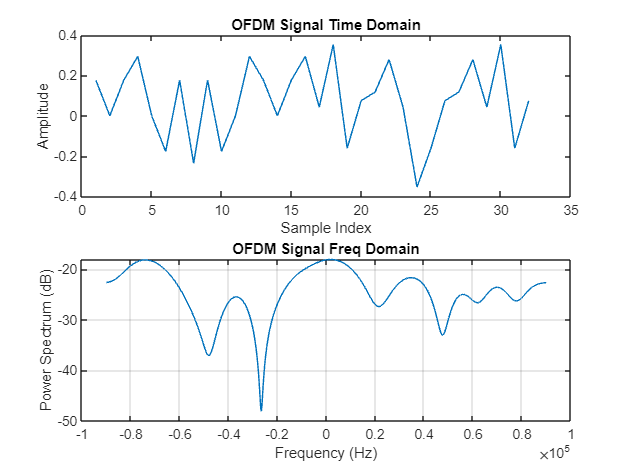


if plotSpec 
    % Plot the time domain signal
    figure;
    subplot(2,1,1);
    plot(real(ofdmTimeSignal));
    title('OFDM Signal Time Domain');
    xlabel('Sample Index');
    ylabel('Amplitude');
    
    [pxx,f] = pspectrum(ofdmTimeSignal,Fs);
    subplot(2,1,2);
    plot(f,pow2db(pxx))
    grid on
    title('OFDM Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

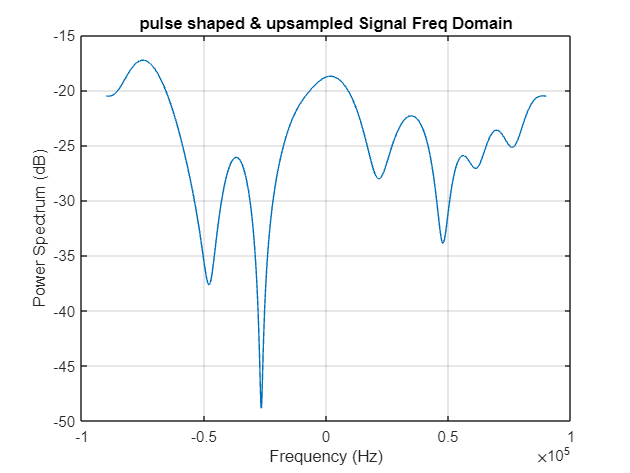


%upsampling & pulse shaping
%L = 2;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(ofdmTimeSignal, L);

rrcFilter = rcosdesign(rolloff, span, L);
%impz(rrcFilter)
if enableFilters
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');
else
    txSignalShaped = txSignalUpsampled;
end

if plotSpec   
    [pxx,f] = pspectrum(txSignalShaped,Fs);
    figure
    plot(f,pow2db(pxx))
    grid on
    title('pulse shaped & upsampled Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

## channel & rx